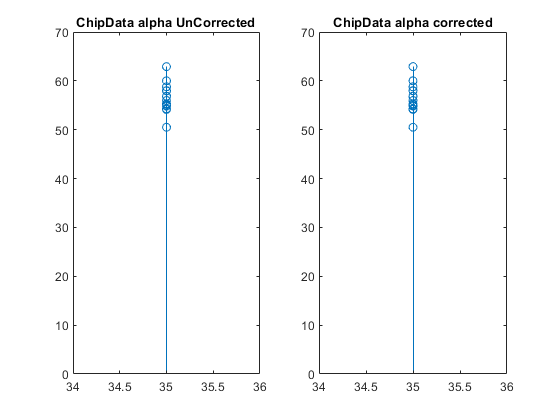

clear;
clc;
%load('alphaData.mat');
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaUNCorrected\alphaUNCorrected.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\alphaCorrected_4X_MAC155_SUB_120.mat');



%8-Bit Weights
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat')


figure();
subplot(1,2,1)
dataDL=adc_VPVN;
dataDLMAcs=((reshape(dataDL,88,4,[])/0.9)*40)+120;%MACs
MSB_powers=2.^[1 0 -1 -2];MSB_powers(1)=-MSB_powers(1);
LSB_powers=2.^[-3 -4 -5 -6];
powerCombs=cat(3,repmat(MSB_powers,72,1,size(dataCols,1)),repmat(LSB_powers,72,1,size(dataCols,1)));
arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,size(dataCols,1),2);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = sum(dataCols,2)-sum(refCols,2);
stem(x_array ,-dataDLMAcs(:,36));

title('ChipData alpha UnCorrected');

subplot(1,2,2)
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\alphaCorrected_4X_MAC155_SUB_120.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat')

%figure();
dataDL=adc_VPVN;
dataDLMAcs=((reshape(dataDL,88,4,[])/0.9)*40)+120;%MACs
MSB_powers=2.^[1 0 -1 -2];MSB_powers(1)=-MSB_powers(1);
LSB_powers=2.^[-3 -4 -5 -6];
powerCombs=cat(3,repmat(MSB_powers,72,1,size(dataCols,1)),repmat(LSB_powers,72,1,size(dataCols,1)));
arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,size(dataCols,1),2);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = sum(dataCols,2)-sum(refCols,2);
stem(x_array ,-dataDLMAcs(:,36));

title('ChipData alpha corrected');

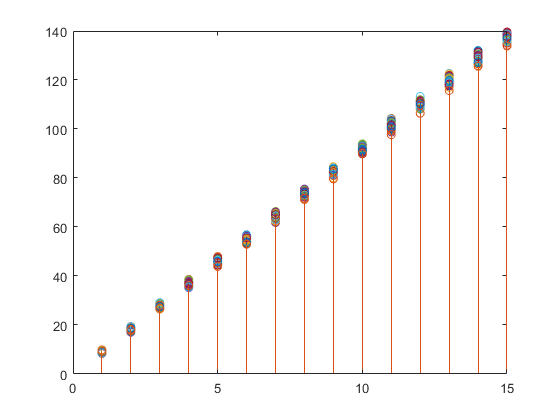



load('dataWeights.mat');
load('dataCols.mat');
wtX=zeros(15,72,8);
for wt_MSBbits=0:1
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
    end
end
wtX=sum(wtX,3);
figure();
stem(wtX);

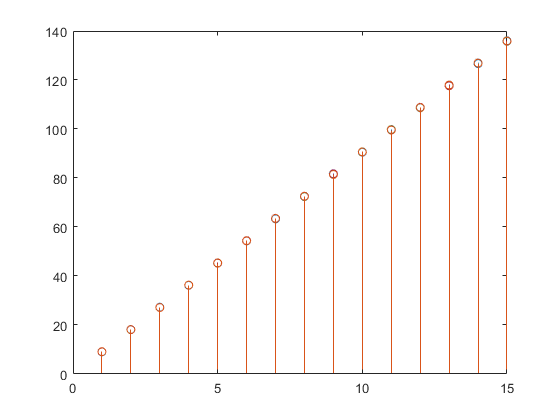


load('origAlphaData.mat')
load('dataWeights.mat');
load('dataCols.mat');
wtX=zeros(15,72,8);
wtSVolt=zeros(15,72,8);
alpha_DLs=[alpha_DLs;zeros(1092-1024,72)];
for wt_MSBbits=0:1
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        data_DL=data_DL.*alpha_DLs;
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
        wtSVolt(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*(0.9/160);
    end
end
wtX=sum(wtX,3);
figure();
stem(wtX);

figure();
powerS=repmat(reshape([MSB_powers,LSB_powers],1,1,[]),15,72,1);
stem(sum(wtSVolt.*powerS*(160/0.9),3));